addpath("C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6\import-data")
warning('off','all')

figure;
AoA = [6]

AoA = 6

M = [2.00]

M = 2

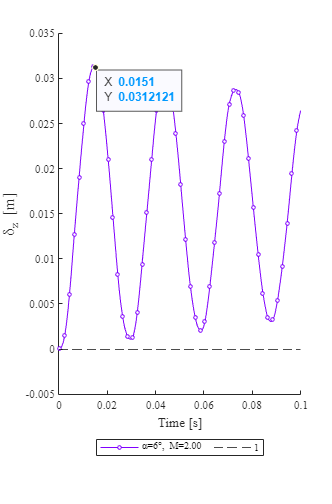

filenamestring = ".\graphs\zDisp-Graph-6deg.png"



colorbank = {[128, 0, 255]/256 [0, 32, 255]/256 [0, 128, 255]/256 [0, 255, 255]/256 [0, 255, 0]/256 [255, 191, 0]/256 [255, 128, 0]/256 [255, 0, 0]/256 [255, 0, 191]/256 'm' 'm' 'm' 'm'};
markerbank = {'o' '^' 'd'};
markersize = 3; markerindices = 5:20:1000; markerfacecolor = 'w'; linewidth = 0.8;

StructData = cell(length(AoA),length(M));
zDispLines = gobjects(size(StructData));
LegendLabels = string(size(StructData));

for ind_AoA=1:length(AoA)
    figure;
    for ind_M=1:length(M)
        StructData{ind_AoA,ind_M} = importStructData(AoA(ind_AoA), M(ind_M));
        zDispLines(ind_AoA,ind_M) = line(StructData{ind_AoA,ind_M}.Time, StructData{ind_AoA,ind_M}.zDisp);
        zDispLines(ind_AoA,ind_M).Marker = markerbank{ind_AoA};
        zDispLines(ind_AoA,ind_M).MarkerSize = markersize;
        zDispLines(ind_AoA,ind_M).MarkerIndices = markerindices;
        zDispLines(ind_AoA,ind_M).MarkerFaceColor = markerfacecolor;
        zDispLines(ind_AoA,ind_M).LineWidth = linewidth;
        zDispLines(ind_AoA,ind_M).Color = colorbank{ind_M};
        LegendLabels(ind_AoA,ind_M) = "\alpha=" + StructData{ind_AoA,ind_M}.AoA + "°, M=" + StructData{ind_AoA,ind_M}.MachNumber;
    end

yline(0,'k--',LineWidth=linewidth)

xlim([0,0.1])
xlabel("Time [s]",FontSize=11)
ylabel("\delta_z [m]",FontSize=13)
ylim([-0.005,0.035])

legend(LegendLabels(ind_AoA,:),Location="southoutside",NumColumns=3)
figposition = [10,10,500,800];
set(gcf,"Position",figposition);
set(gca,'FontName','Times');

filenamestring=".\graphs\zDisp-Graph-" + num2str(AoA(ind_AoA)) + "deg.png"
%exportgraphics(gcf,filenamestring,"Resolution",300,"BackgroundColor","none",ContentType="vector")
end